# Project 1: Epidemiology

*Authors: *Drew Pang and Emma Mascillaro

Epidemiology, or the study of disease spread, is essential in understanding the diseases all around us. This is ever more apparent today, as the results of COVID-19 models drive the public health interventions and help us plan for the future. Although not an appropriate model for COVID-19, the SIR model can be used to model many other infectious diseases. Through abstraction, we want to take a real-world scenario and generate a simplification of it. However, we must maintain some level of accuracy whereby our model accounts for enough factors to be reasonable but not too many to lose focus of the question. Let's define the real-world scenario we wish to model:

**Question:** How long will the disease outbreak modeled in the SIR Notebooks last if we account for vaccinations and reinfections?

#### **Methodology:**

**Model #1:  Standard SIR Model**

In the original SIR Model, there are three stocks and two flows, where the stocks are collections of people and the flows are the rates at which people move between stocks.

*Stocks:*                                                                *Flows:*

- Suscueptible (S)                                        - Beta ($\beta$)

- Infected (I)                                                 -  Gamma ($\gamma$)

- Recovered (R)

In the standard SIR model, people can only flow from susceptible to infected and from infected to recovered, as shown below.

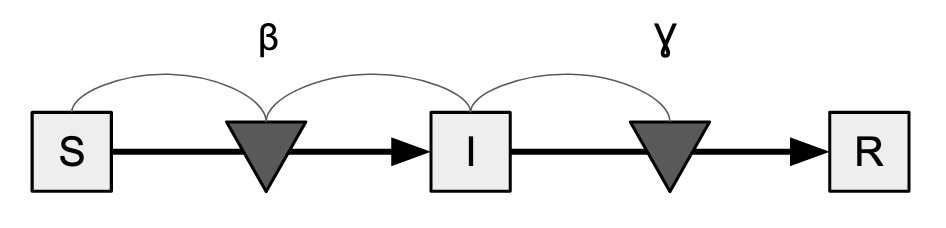

To model how people move between the stocks in this scenario, we can use the following equations:

$S_{t+1} = S_t - \Delta I_t \\
I_{t+1} = I_t + \Delta I_t  - \Delta R_t \\
R_{t+1} = R_t+ \Delta R_t \\$                 or                $S_{t+1} = S_t - \beta S_tI_t \\
I_{t+1} = I_t + \beta S_tI_t - \gamma I_t \\
R_{t+1} = R_t+ \gamma I_t \\$

These equations are then implemented in as shown in the sir_step function below

%{

% Computation taken from the sir_step function:

% compute new infections and recoveries
infected = beta * i * s;
recovered = gamma * i;
    
% Update state
s_n = s - infected;
i_n = i + infected - recovered;
r_n = r + recovered;

%}

**Model #2:  Accounting for Vaccines and Reinfection**

In order to improve on the previous model, we decided to add two more flows: Mu ($\mu$) to account for the vaccination rate and Lambda ($\lambda$) to account for reinfections.  In this new system, people flow between stocks as shown in the diagram below:

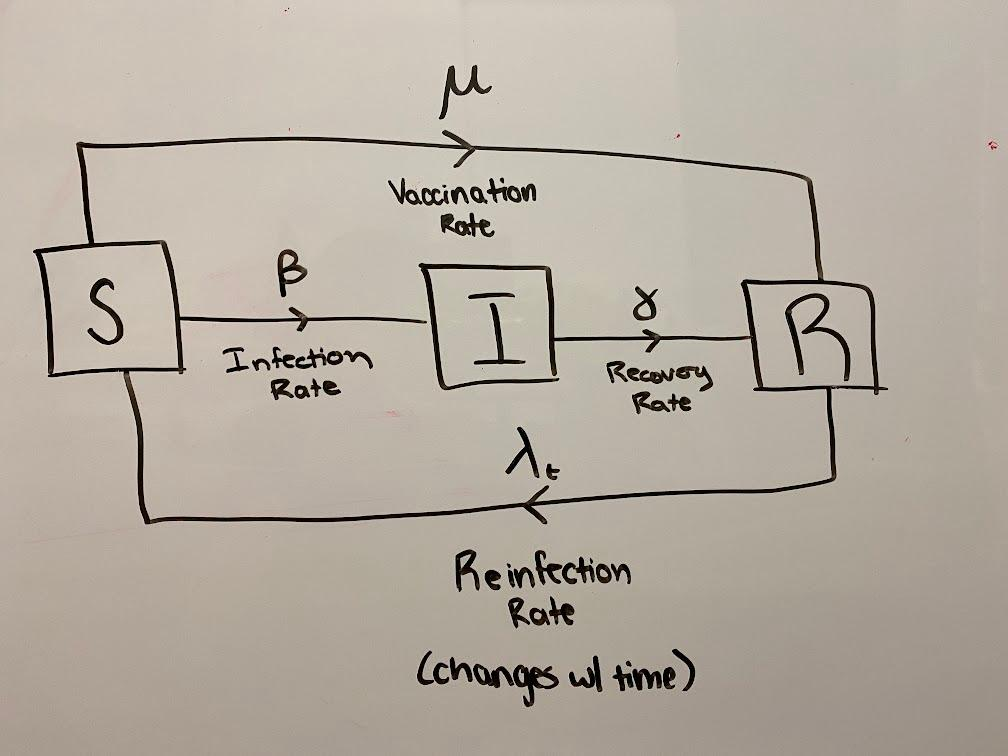

Therefore, the new equations to represent the flow of people between stocks in this model, accounting for $\mu$ and $\lambda$, would be the equations below:


$$S_{t+1} = S_t - \beta S_t I_t - \mu S_t + \lambda R_t I_t\\
I_{t+1} = I_t + \beta S_t I_t - \gamma I_t\\
R_{t+1} = R_t + \gamma I_t - \lambda R_t I_t + \mu S_t$$


These equations are then implemented in as shown in the sir_step_project function below

%{

% Computation taken from the sir_step_project function:

s_n = s - beta*s*i - mu*s + lambda*step*r;
i_n = i + beta*s*i - gamma*i;
r_n = r + gamma*i - lambda*step*r + mu*s;

%}

If given more time, we would validate our model by researching parameters and data already existent for applicable infectious diseases and analyze how well our model follows their trajectory, potentially fitting our data to match real-world data.

#### **Results:**

**Running Model #1:**

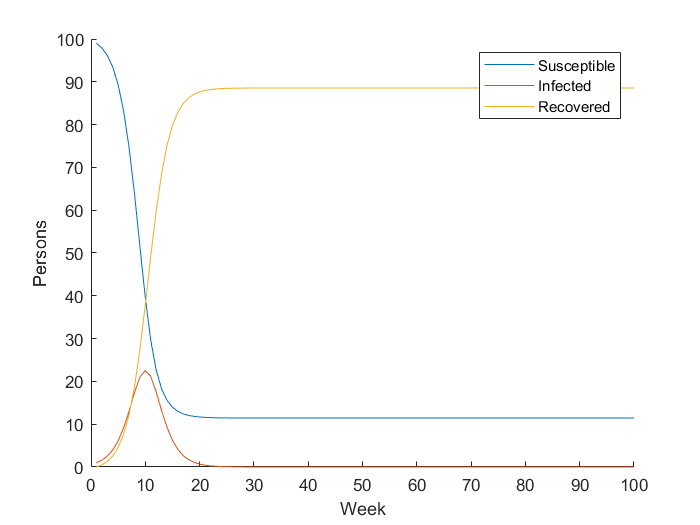

% Sets the initial number of people in each stock
s_0 = 99;
i_0 =  1;
r_0 =  0;


% Sets the flow values
beta = 1/90;
gamma = 1/2;

% Sets the number of weeks for the duration of the model
num_steps = 100;

% Run simulation
[S, I, R, W] = sir_simulate(s_0, i_0, r_0, beta, gamma, num_steps);

% Plot
figure(1); clf; hold on;
plot(W, S); label1 = "Susceptible";
plot(W, I); label2 = "Infected";
plot(W, R); label3 = "Recovered";

xlabel("Week")
ylabel("Persons")
legend({label1, label2, label3})

After ten weeks, the population reaches a peak number of infections, and after approximately 23 weeks, the number of infected persons returns to approximately zero.

**Running Model #2:**

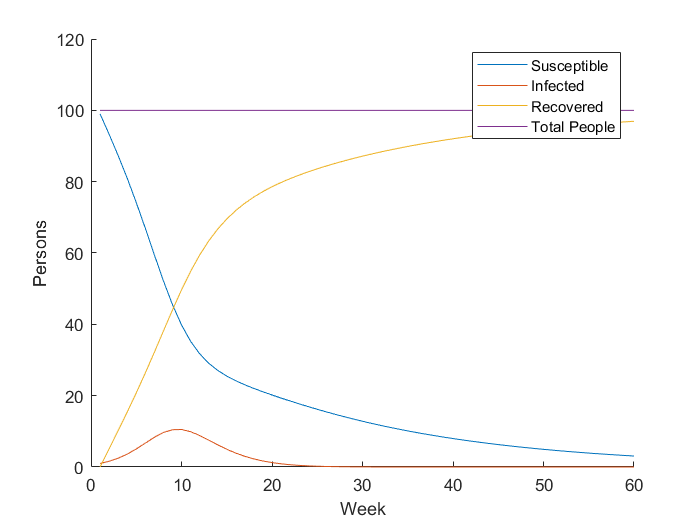

% Sets the initial number of people in each stock
s_0 = 99;
i_0 =  1;
r_0 =  0;

% Sets the flow values
beta = 1/90;
gamma = 1/2;
mu = 4.65/100;
lambda = 1/270;


% Sets the number of weeks for the duration of the model
num_steps = 60;

[s_n, i_n, r_n, W] = sir_simulate_project(s_0, i_0, r_0, beta, gamma, lambda, mu, num_steps);

% Plot
figure(1); clf; hold on;
plot(W, s_n); label1 = "Susceptible";
plot(W, i_n); label2 = "Infected";
plot(W, r_n); label3 = "Recovered";

plot(s_n + i_n + r_n); label4 = "Total People"; % Ensures that people are conserved

xlabel("Week")
ylabel("Persons")
legend({label1, label2, label3, label4})

The population reaches the first peak number of infections after 10 weeks, the second peak around 38 weeks, and the third peak at around 57 weeks.  Each of these waves is flatter than the previous, however, the number of infections remains increasing.  We believe that this is due to an underlying logical error.

**Model Fitting:**

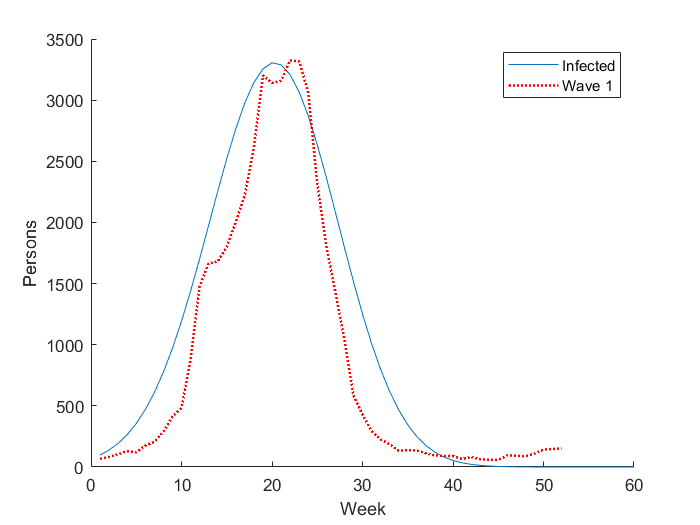

% Load the validation data
data = readtable("data", "Delimiter", ",");

% Sets the initial number of people in each stock
s_0 = 326800000;
i_0 =  98;
r_0 =  0;

% Sets the flow values
beta = 29090/4490000000000;
gamma = 1.7;
mu = 465/40000;
lambda = beta*.17;


% Sets the number of weeks for the duration of the model
num_steps = 60;

[s_n, i_n, r_n, W] = sir_simulate_project(s_0, i_0, r_0, beta, gamma, lambda, mu, num_steps);

% Plot
figure(1); clf; hold on;
plot(W, i_n); label1 = "Infected";
plot(data.W, data.I, 'r:', 'LineWidth', 1.5); label2 = "Wave 1";


xlabel("Week")
ylabel("Persons")
legend({label1, label2})


*****PARAMETER SWEEP: Increasing Vaccination Rate**

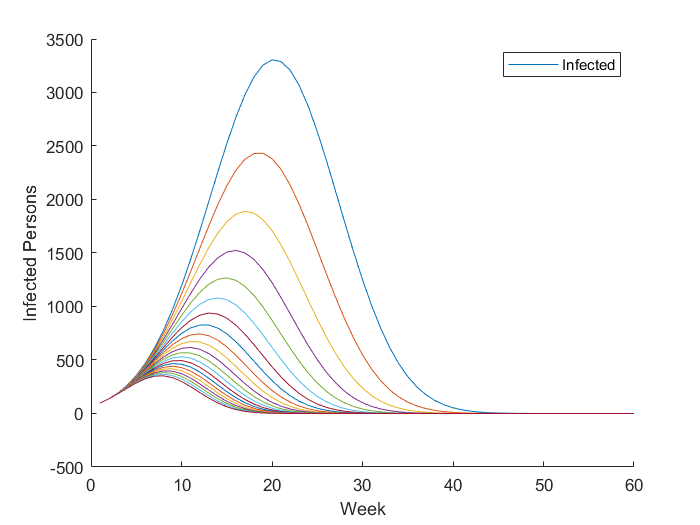

clf
hold on
% Sets the initial number of people in each stock
s_0 = 326800000;
i_0 =  98;
r_0 =  0;

% Sets the flow values
beta = 29090/4490000000000;
gamma = 1.7;
mu = 465/40000;
lambda = beta*.17;

% Sets the number of weeks for the duration of the model
num_steps = 60;

%mu_v = [(0/3)*mu, (1/3)*mu, (2/3)*mu, (3/3)*mu, (4/3)*mu, (5/3)*mu, (6/3)*mu];


for mu = mu : (1/10)*mu : 3*mu

    [s_n, i_n, r_n, W] = sir_simulate_project(s_0, i_0, r_0, beta, gamma, lambda, mu, num_steps);
    
    % Plot
    figure(1);
    plot(W, i_n);
end

xlabel("Week")
ylabel("Infected Persons")
legend({label1})
hold off

*****PARAMETER SWEEP: Decreasing Vaccination Rate**

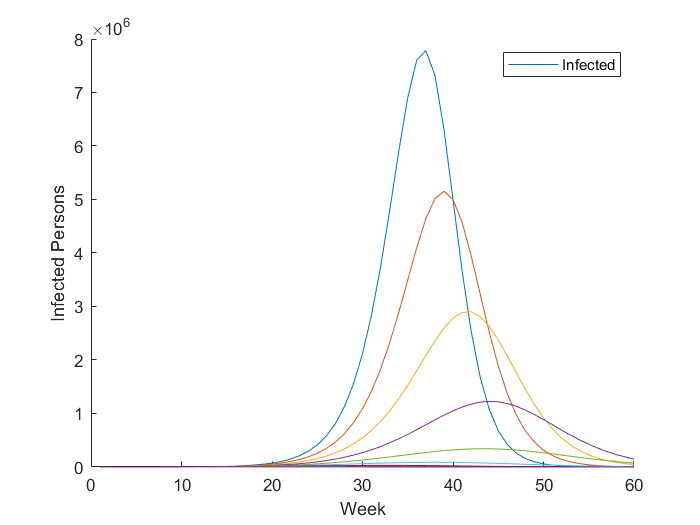

clf
hold on
% Sets the initial number of people in each stock
s_0 = 326800000;
i_0 =  98;
r_0 =  0;

% Sets the flow values
beta = 29090/4490000000000;
gamma = 1.7;
mu = 465/40000;
lambda = beta*.17;

% Sets the number of weeks for the duration of the model
num_steps = 60;

%mu_v = [(0/3)*mu, (1/3)*mu, (2/3)*mu, (3/3)*mu, (4/3)*mu, (5/3)*mu, (6/3)*mu];


for mu = 0*mu : (1/10)*mu : mu

    [s_n, i_n, r_n, W] = sir_simulate_project(s_0, i_0, r_0, beta, gamma, lambda, mu, num_steps);
    
    % Plot
    figure(1);
    plot(W, i_n);
end

xlabel("Week")
ylabel("Infected Persons")
legend({label1})

hold off

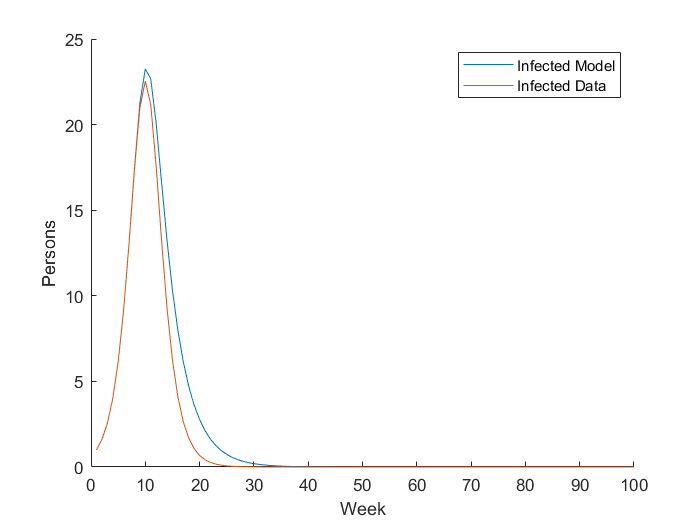

% Sets the initial number of people in each stock
s_0 = 99;
i_0 =  1;
r_0 =  0;

% Sets the flow values
beta = 1/90;
gamma = 1/2;
mu = 0;
lambda = 1/270;

% Sets the number of weeks for the duration of the model
num_steps = 100;

[s_n, i_n, r_n, W] = sir_simulate_project(s_0, i_0, r_0, beta, gamma, lambda, mu, num_steps);

% Plot
figure(1); clf; hold on;
plot(W, i_n); label1 = "Infected Model";

plot(W, I); label2 = "Infected Data";

xlabel("Week")
ylabel("Persons")
legend({label1, label2})

#### **Interpretation:**

Our model outputs a graph with two waves, meaning that our reinfection flow is working. Nevertheless, our infected stock continues to rise past the peak of wave 2 around week 39. This reveals a fundamental flaw with our model, where people get stuck in a loop of recovery and reinfection. We will need to revisit how we define the reinfection flow such that our model aligns more with a real-world scenario. 